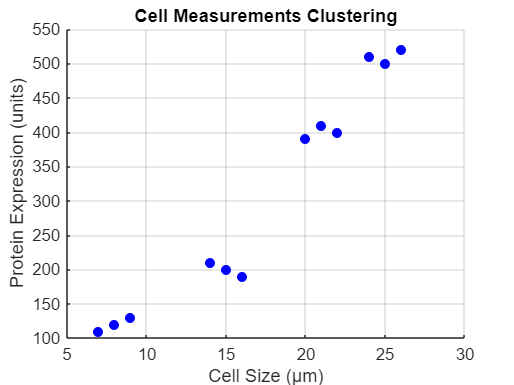

clc; clear; close all;

% Step 1: Input the data as column vectors
cell_size = [15, 16, 14, 22, 21, 20, 8, 9, 7, 25, 26, 24]';
protein_expression = [200, 190, 210, 400, 410, 390, 120, 130, 110, 500, 520, 510]';

% Step 2: Combine into a 12x2 matrix
data = [cell_size, protein_expression];

% Step 3: Scatter plot for visualization
figure;
scatter(cell_size, protein_expression, 'bo', 'filled');
xlabel('Cell Size (μm)');
ylabel('Protein Expression (units)');
title('Cell Measurements Clustering');
grid on;


% Step 4: Choose k (observe plot for natural grouping)
k = 3; % Adjust if necessary

% Step 5: Perform K-Means Clustering
[idx, centroids] = kmeans(data, k, 'Start', 'plus');

% Step 6: Display cluster centers
disp('Cluster Centers:');

Cluster Centers:


disp(centroids);

    25   510
     8   120
    15   200
    21   400



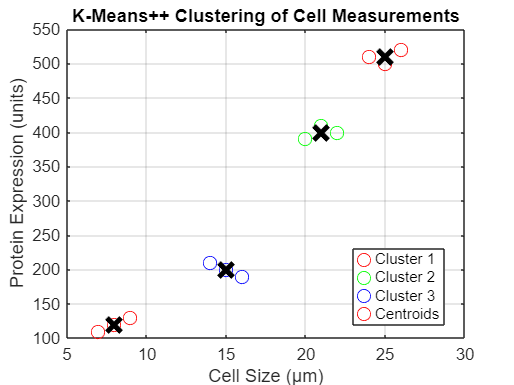


% Step 7: Perform K-Means++ Clustering
[idx2, centroids2] = kmeans(data, k, 'Start', 'plus');

% Step 8: Visualize with colors for clusters
figure;
gscatter(data(:,1), data(:,2), idx2, 'rgb', 'o', 8);
hold on;
plot(centroids2(:,1), centroids2(:,2), 'kx', 'MarkerSize', 12, 'LineWidth', 3);
xlabel('Cell Size (μm)');
ylabel('Protein Expression (units)');
title('K-Means++ Clustering of Cell Measurements');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Centroids');
grid on;
hold off;